##  ECE 537 : Assignment 4

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1:** Load the Exercise 4 data set. This data comprises 1000 samples from 2 classes in 100 measurement dimensions.

Solution:

load('Exercise_4_Data.mat')

**Task 2: **Comment on whether the available data represents a dense sampling of this high dimensional space and, if you assumed both data classes were Gaussian distributed, then discuss how many data samples would be required to provide a sufficient dense sampling of the data across all of its dimensions.

Solution: 

The available data represents an incredibly sparse sampling of this high dimensional space. In one dimension, a sufficiently dense representation of Gaussian data would require ~100 data points. As the dimensionality of the space increases the number of points required to accurately represent Gaussian data would be characterized by 100^d, where d indicates the dimensionality. In our case that would mean that 100^100 data points are required. It is worth noting that this number of data points is completely unfeasible, as it is more data points than there are atoms in the known universe.

**Task 3: **Randomly partition the data into training and test sets where the training set represents 25% of the data and the test set represents the remaining 75% of the data.

Solution:

train_data = a(Train_indx,:); % 25% of the data
train_labels = classes(Train_indx);
test_data = a(Test_indx,:); % 75% of the data
test_labels = classes(Test_indx);

**Task 4: **Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply this dimensionality reduction to the test data.

Solution:

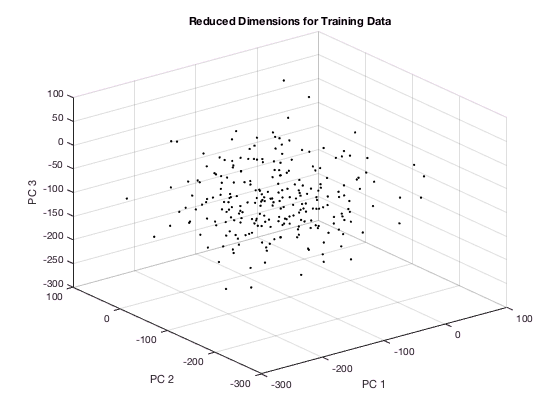

%reduce the dimensions
q = 3; %number of dimensions to reduce
Uq = PCA_fun(train_data,q); % dimensionality reduction vectors
train_proj = train_data*Uq; % reduced training data 
test_proj = test_data*Uq; % reduced testing data 

figure(1)
plot3(train_proj(:,1),train_proj(:,2),train_proj(:,3),'.k','linew',1.5)
xlabel('PC 1')
ylabel('PC 2')
zlabel('PC 3')
title('Reduced Dimensions for Training Data')
grid on ;

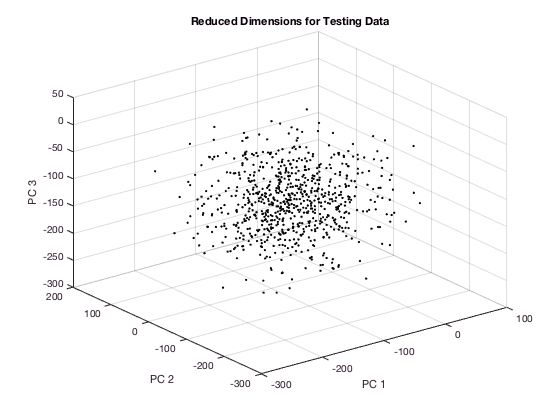


figure(2)
plot3(test_proj(:,1),test_proj(:,2),test_proj(:,3),'.k','linew',1.5);
xlabel('PC 1')
ylabel('PC 2')
zlabel('PC 3')
title('Reduced Dimensions for Testing Data')
grid on ;

**Task 5:** Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.

Solution:

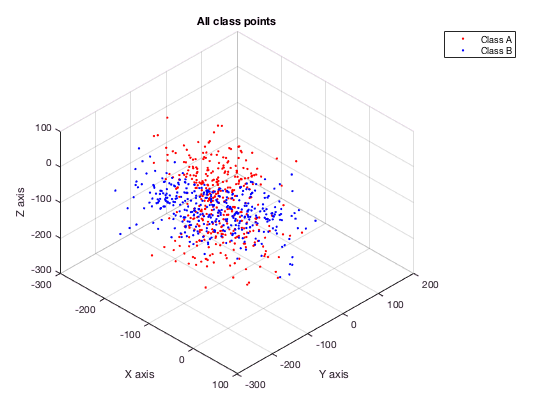

% Prepare training data and labels
class_A_train = train_proj(train_labels==0,:);
mu_A = mean(class_A_train);
sigma_A = cov(class_A_train);
class_B_train = train_proj(train_labels==1,:);
mu_B = mean(class_B_train);
sigma_B = cov(class_B_train);
%priori probabilities
pwA = nnz(train_labels==0)/length(train_labels);
pwB = 1-pwA;
%likelihood
pxwA = gaussian_density(mu_A,sigma_A,test_proj);
pxwB = gaussian_density(mu_B,sigma_B,test_proj);

%evidence
px = pxwA*pwA + pxwB*pwB; 

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);

%visualization

[~,class_index] = max([gA gB],[],2);

figure(3)
visualize_points(class_index, test_proj);
title('PCA Reduction of All Class Points')
legend('Class A','Class B')


% Predicted class values 
prediction = class_index-1;

%classification accuracy
classification_accuracy_PCA = nnz(prediction == test_labels')/length(test_labels) %class index is in terms of 1 and 2 while test_labels are in terms of 0 and 1

classification_accuracy_PCA = 0.5000

Comments : The classification performance acheived with PCA is quite poor (50%). This however is expected since PCA is meant as a means of representation and is not ideal for classification.  PCA appears to discard features significant for classifying the data. This is elaborated upon below in task 6. 

**Task 6: **Discuss whether PCA is a correct approach to apply for addressing classification problems and present clear arguments as to why (or why not).

Solution:

PCA is not the correct approach to apply for addressing classification problems. In our case PCA actually removes the information that makes the data completely separable. PCA has no knowledge of classes and their labels and therefore has no way to account for/separate them.  It reduces the dimensionality of a feature space by restricting attention to directions along which the scatter of all the data points is the greatest, making it efficient for representation and visualization but often inefficient for classification. 

**Task 7:** Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension.

Solution:

class_A_tr = train_data(train_labels==0,:); % Traning data in class A
class_B_tr = train_data(train_labels==1,:); % Traning data in class B

Vs = LDA_fun(class_A_tr,class_B_tr); % dimensionality reduction vector

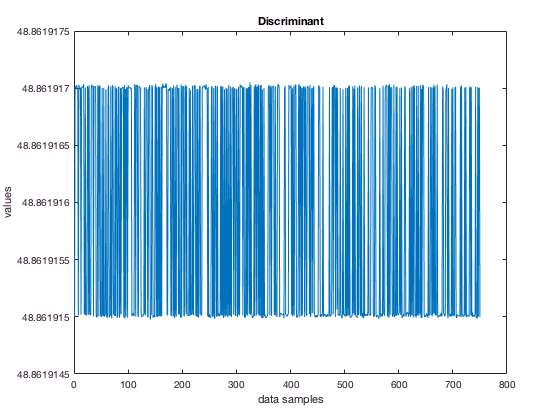

train_LDA_proj = (Vs'*train_data')'; % reduced training data
test_LDA_proj = (Vs'*test_data')'; % reduced testing data 

figure(4)
plot(test_LDA_proj)
xlabel('data samples')
ylabel('values')
title('Discriminant')

**Task 8:** Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.

Solution:

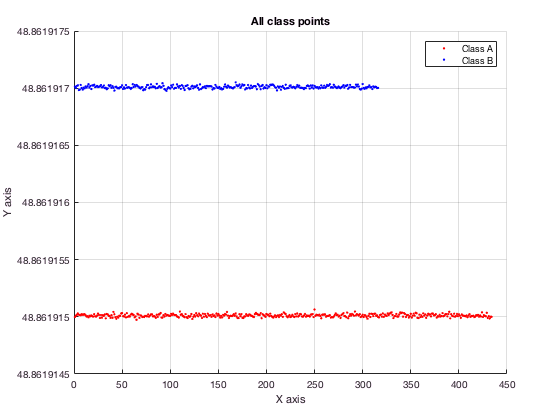

class_A_train = train_LDA_proj(train_labels==0);
mu_A = mean(class_A_train);
sigma_A = cov(class_A_train);

class_B_train = train_LDA_proj(train_labels==1);
mu_B = mean(class_B_train);
sigma_B = cov(class_B_train);

%priori probabilities
pwA = nnz(train_labels==0)/length(train_labels);
pwB = 1-pwA;

%likelihood
pxwA = gaussian_density(mu_A,sigma_A,test_LDA_proj);
pxwB = gaussian_density(mu_B,sigma_B,test_LDA_proj);

%evidence
px = pxwA*pwA + pxwB*pwB; 

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);

%visualization

[~,class_index] = max([gA gB],[],2);

figure(5)
XA = test_LDA_proj(class_index == 1,:);
XB = test_LDA_proj(class_index == 2,:);

axes_plot = axes;
hold(axes_plot,'on');
plot(XA,'Marker','.','LineStyle','none','Color','r');
plot(XB,'Marker','.','LineStyle','none','Color','b');

xlabel('X axis');
ylabel('Y axis');
grid(axes_plot,'on');
hold(axes_plot,'off');

title('All class points')
legend('Class A','Class B')


prediction = class_index-1;

%classification accuracy
classification_accuracy_LDA = nnz(prediction == test_labels')/length(test_labels)%class index is in terms of 1 and 2 while test_labels are in terms of 0 and 1

classification_accuracy_LDA = 1

Comments: The classification here is 100%. This is understandable since the data was reduced using a Fishers based approach which seeks to maximize between class scatter and minimize within class scatter, therefore making it an ideal dimensionality reduction technique for classification. 

**Task 9: **Discuss the characteristics of the resulting dimensionality reduction vector and the Fisher-based approach was able to classify the data versus the results obtained for the PCA-based approach.

Solution:

The resulting dimensionality reduction vector is simply a weighting of the importance of each of the features provided in the original dataset. In our case, we can see that the vector returned by the Fisher-based approach is essentially all zeros except for a single entry, where it is 1. This means that in order to effectively reduce the dimensionality and separate the classes only a single feature is required. This in turn is the reason that the data returned by the Fisher-based approach is completely separable. Once again, PCA does not take into account class labels and is therefore not an optimal solution for dimensionality reduction if classification is the end goal.  

**Task 10: **Discuss whether the performance of PCA would have improved if a higher percentage of the data was used in training the PCA system.

Solution:

Because PCA is not designed for discriminating data (see explanation in Task 6), there is no reason to believe a larger training set would lead to improved classification results.  Below is an example of PCA performed on the same dataset with the training sets and the testing set swapped (which in this case translates to 75% training data, 25% testing data). The classification accuracy here is 1.2% higher than it was with a 25% training 75% testing split, which proves that a larger training set will not significantly impact the classification accuracy.

train_swap_data = test_data; % Letting the training dataset be 75% of the data
train_swap_labels = test_labels;
test_swap_data = train_data; % Letting the testing dataset be 25% of the data 
test_swap_labels = train_labels;

q = 3; %number of dimensions to reduce
Uq = PCA_fun(train_swap_data,q); 
train_swap_proj = train_swap_data*Uq;
test_swap_proj = test_swap_data*Uq;

%prepare train_swaping data and labels
class_A_train_swap = train_swap_proj(train_swap_labels==0,:);
mu_A = mean(class_A_train_swap);
sigma_A = cov(class_A_train_swap);

class_B_train_swap = train_swap_proj(train_swap_labels==1,:);
mu_B = mean(class_B_train_swap);
sigma_B = cov(class_B_train_swap);

%priori probabilities
pwA = nnz(train_swap_labels==0)/length(train_swap_labels);
pwB = 1-pwA;
%likelihood
pxwA = gaussian_density(mu_A,sigma_A,test_swap_proj);
pxwB = gaussian_density(mu_B,sigma_B,test_swap_proj);

%evidence
px = pxwA*pwA + pxwB*pwB;

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);

[~,class_index] = max([gA gB],[],2);
prediction = class_index-1;

%classification accuracy
classification_accuracy_swapped_PCA = nnz(prediction == test_swap_labels')/length(test_swap_labels) %class index is in terms of 1 and 2 while test_swap_labels are in terms of 0 and 1

classification_accuracy_swapped_PCA = 0.5120

**Task 11: **Use Matlab's neural network toolbox to train a neural network on the original data set, while using a randomly selected 25% of the data as the training and the remaining data as the test data.

Solution:

% Neural Network parameters
data = a;
targets = (classes+1)';
train_test_split  = 0.75;
hidden_layer = 10;

[class_index,e,performance,percentErrors] = nn__classifier(data,targets,train_test_split,hidden_layer);

Undefined function 'patternnet' for input arguments of type 'double'.

Error in A4_submission>nn__classifier (line 284)
    net = patternnet(hiddenLayerSize, trainFcn);

[max_error,~] = max(abs(e));
MSE=  sum(max_error.*max_error,2)/length(max_error)

performance
percentErrors
classification_accuracy_NN = nnz(class_index == targets' )/length(classes)

**Task 12: **Discuss the resulting neural network's ability to correctly classify this data set, in comparison to the results produced under PCA and Fisher and, in particular, the differences and distinctions between the knowledge gained about the problem domains between the neural network and Fisher approaches and whether this would continue to hold for non-linearly separable problem domains

Solution: 

For this dataset Fisher discriminant analysis approach was able to classify with 100% accuracy since the data was linearly seperable in one dimension.  Neural networks are essentially blackboxes, where it tries to minimize a preselected cost function. The neural network classifies with 100% accuracy. Fishers approach tell us which dimension is useful for classifying this data i.e.  in Fisher 's approach we transform to lower dimension using a projection vector where all of the entries are approximately zero except one entry.  PCA fails to accurately classify the samples in the dataset (< 50%) , PCA doesnt use the class labels and while reducing the dimension it threw away most of the information which made perfectly linearly seperable data inseperable. Comparing three approaches, Fisher provides the information regarding which dimension is useful for seperating this data, PCA makes the data inseperable and Neural network was able to match Fishers performance but didn't provide any knowledge about the problem domain. Overall we can say that Fisher discriminant approach is most preferable for such linearly seperable data because of its less complexity as compared to neural networks.  For Non-linearly seperable problem domains, neural network would work best since it is a non-linear technique whereas PCA and LDA being linear techniques would not work well for non-linear data.

**Task 13:  **Now remove the feature vector identified through the Fisher analysis and retrain a new neural network based on this data. Discuss the classification performance that this classifier achieves and the overall distribution of classification performances that such a classifier could be seen to achieve.

a_new = a;
a_new(:,Vs == max(Vs)) = [];
train_test_split  = 0.75;
hidden_layer = 10;

[class_index_r,e_r,performance_r,percentErrors_r] = nn__classifier(a_new,targets,train_test_split,hidden_layer);
[max_error_r,~] = max(abs(e_r));
MSE_r=  sum(max_error_r.*max_error_r,2)/length(max_error_r)

performance_r
percentErrors_r
class_acc_NN_r = nnz(class_index_r == targets' )/length(classes)

Comments:

When the feature vector identified from the Fisher analysis was removed from the original dataset, the performance of the neural network decreased significantly in terms of classification accuracy and mean squared error. This is because this feature vector was more significant as compared to other feature vectors in classifying this linearly seperable data. Overall, if a most significant feature is removed from the data, it would result in a largest decline in accuracy.

**Task 14:** Discuss whether it would be common in operational data analysis settings for dense data samplings to be available a priori from which analytics systems could then be trained or whether this is more likely to occur rarely. Discuss the implications this has one training data analytics systems and, particularly, the selection of measurement features based on the analyses of available data.

Solution: 

It is not common in operational data analysis settings for dense data samplings to be available apriori since collecting and labelling large set of patterns is pretty expensive. Furthermore, data may contain many features as well as many attributes of each feature and large amounts of data require more storage, which inturn demands powerful hardware and softwares. Also, data maintainence and conversion is often very expensive in data which employs dynamic features. Therefore, as the dimensionality of the data increases, the liklihood of finding sufficently dense apriori datasets in operational data analysis settings decreases dirastically. This is something to be cautious of when training analytical systems as it may lead to inaccurate results. The ideal situation when dealing with higher dimensional data is that many of the features are not significant and can be dropped, thus increasing the density of the available data samples.

function Uq = PCA_fun(data,q)
    mu = mean(data);%calculate mean of the data
    dh = data-mu;%centralize the input data
    C = cov(dh);%calculate the covariance matrix
    [Uq,~] = eigs(C,q);%calculate the q eigen vectors corresponding to the q largest eigen values of the covariance matrix
%     proj = data*Uq;%calculate projection of data points
end

function Vs = LDA_fun(class_A,class_B)
    total_class = [class_A;class_B];
    mu = mean(total_class);
    mu_A = mean(class_A);
    mu_B = mean(class_B);
    dh_A  = class_A - mu_A;
    dh_B = class_B - mu_B;
    %calculate the scatter matrix
    S_A = dh_A'* dh_A;
    S_B = dh_B'*dh_B;
    
    %calculate the within class variance 
    S_W = S_A + S_B;
    %total class scatter
    S_T = (total_class-mu)'*(total_class-mu);
    %within_class scatter
    S_B = S_T - S_W;
    w =S_W\S_B;
% find eigne values and eigen vectors of the (v)
    [V,d]=eigs(w);
    [~, ind] = sort(diag(d),'desc');
    Vs = V(:, ind);
    Vs = abs(Vs(:,1));   
end

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function axes_plot = visualize_points(class_index,V)
    XA = V(class_index == 1,:);
    XB = V(class_index == 2,:);
    
    axes_plot = axes;
    hold(axes_plot,'on');
    plot3(XA(:,1),XA(:,2),XA(:,3),'Marker','.','LineStyle','none','Color','r');
    plot3(XB(:,1),XB(:,2),XB(:,3),'Marker','.','LineStyle','none','Color','b');
   
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis')
    
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end
function [yind,e,performance,percentErrors] = nn__classifier(data,targets,train_test_split,hidden_layer)
%train_test_split gives the fraction of training data over the whole data

    target_new = bsxfun(@eq, targets(:), 1:max(targets)); %one hot encoder
    %neural network classifier
    %use nprtool to open the neural network pattern recognition app
    x = data';
    t = target_new';

    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems.
    % 'trainscg' uses less memory. Suitable in low memory situations.
    trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

    % Create a Pattern Recognition Network
    hiddenLayerSize = hidden_layer;
    net = patternnet(hiddenLayerSize, trainFcn);

    % % Setup Division of Data for Training, Validation, Testing
    net.divideParam.trainRatio = 1 - train_test_split;
    net.divideParam.valRatio = 0;
    net.divideParam.testRatio = train_test_split;

    %decide if you want to show the pop-up window 
    net.trainParam.showWindow = 0;

    % Train the Network
    [net,tr] = train(net,x,t);

    % Test the Network
    y = net(x);
    e = gsubtract(t,y);
    performance = perform(net,t,y);
    tind = vec2ind(t);
    yind = vec2ind(y);
    %y = round(y);
    percentErrors = sum(tind ~= yind)/numel(tind);
end 

